Esto es para el caso en el cual ya no esta dado en una ecuacion diferencial de primer grado, si no, de segundo

# Sistema masa resorte amortiguador

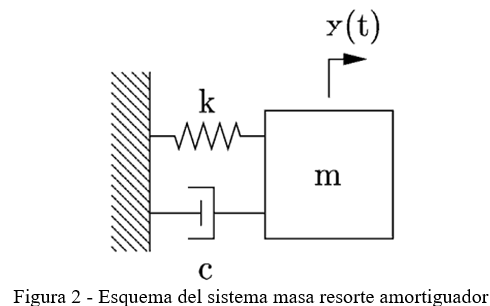


$$m\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x+c\frac{\textrm{d}}{\textrm{d}t}x+\mathrm{kx}=0$$



$$\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x=-\frac{c}{m}\left(\frac{\textrm{d}}{\textrm{d}t}x\right)-\frac{k}{m}x$$


%Entiéndase y(t) como el vector [x;v]
%x'= v, v' = -(c*x)/m - (k*x)/m
%Aun no se como sacamos eso, pero es importante saber.
% Checar el problema de BVP en el cuaderno, se hace algo semejante.
y0 = [1;0];
tf = 15;
h = .1;
m = 20; %kg
k = 20; %N/m

## Sistema sin amortiguamiento

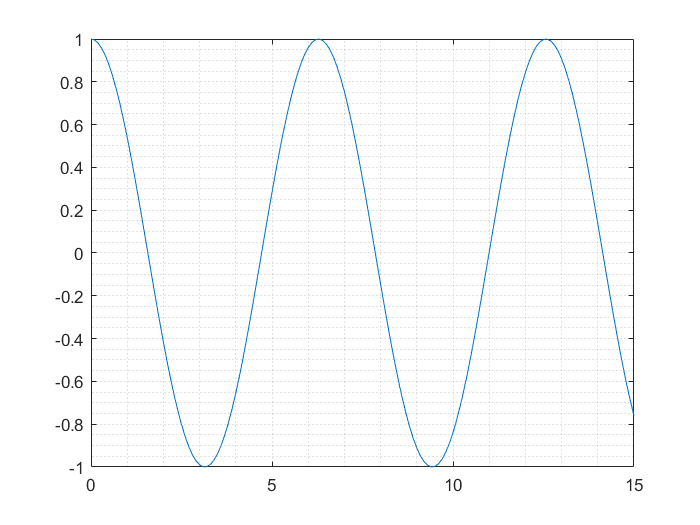

c = 0;
M = [0 1;(-k/m) (-c/m)];
f = @(t,y) M*y;
[t,y] = ivps(f,0,tf,y0,h,4);
plot(t,y(1,:));
grid minor; %Hace aún más fino el grid.

lambda = eig(M);
T = 2*pi*imag(lambda(1))

T = 6.2832

## Sistema sub amortiguado


$$c^2 -\mathrm{mk}<0$$


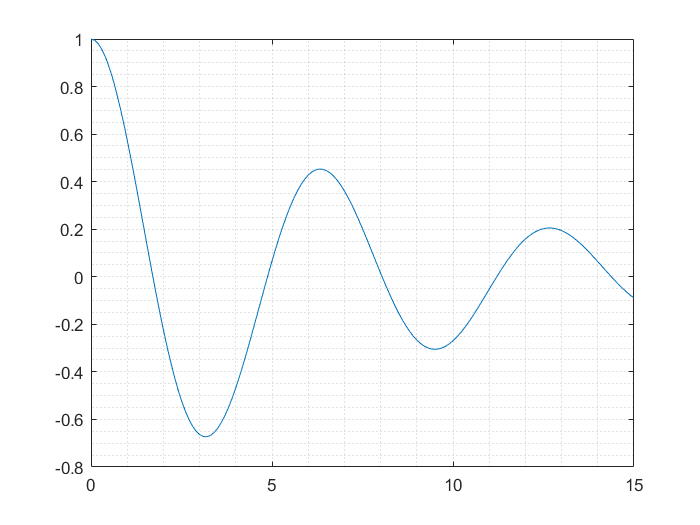

c = 5;
M = [0 1;(-k/m) (-c/m)];
f = @(t,y) M*y;
[t,y] = ivps(f,0,tf,y0,h,4);
plot(t,y(1,:));
grid minor; %Hace aún más fino el grid.

lambda = eig(M);

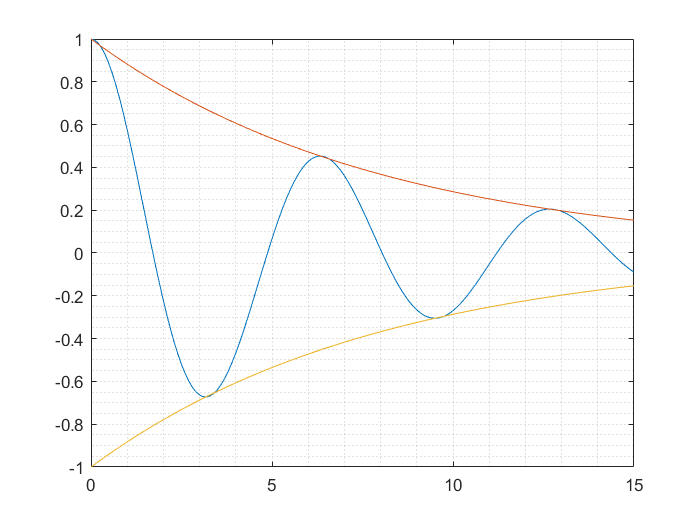

p = real(lambda(1));
hold on;
plot(t,(y0(1)*(exp(p*t))));

plot(t,(-y0(1)*(exp(p*t))));